% Set up a time range for the analysis to do. Do not forget this step!

t = 0:0.02:10;   %vector of time for output, 0 to 10 at 0.02 increments

% Initiate your variables that are fixed.

m = 1;      %value of mass (kg)
L = 1;      %value of length (m)
g = 9.81    %value of gravity acceleration (m/sec^2)

g = 9.8100


% Set up the transfer function from the s-plane

s = tf('s');    %set up transfer function input mode as a alphanumeric variable
sys = (1/(m*L^2))/(s^2 + g/L)   %transfer function

sys =
 
      1
  ----------
  s^2 + 9.81
 
Continuous-time transfer function.



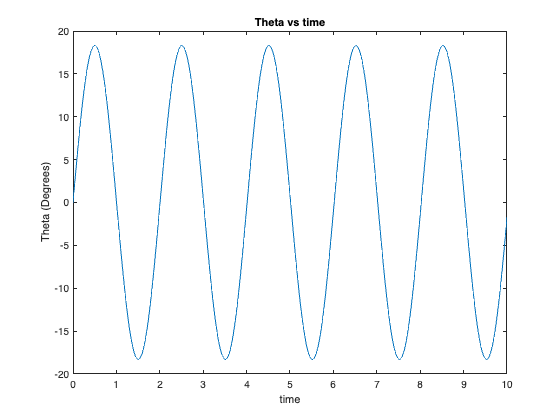


% This function does a step response Y(s) = sys(s) * u(s)
% However it converts it via an inverse Laplace to get the time domain
% y(t) = sys(t) * u(t)
y = impulse(sys,t);    %step response input at t = 0

%set up your output variable in the units you want in this case degrees
Rad2Deg = 57.3;     %converts rads to degrees

% plot your answer with the unit conversions

plot(t,Rad2Deg * y)     %plots y (remember y is in theta!

% Pretty it up with some labels!!

title('Theta vs time')
xlabel('time')
ylabel('Theta (Degrees)')